Simple simulation of the chemostat

%
% Choose a setup:
%
sSetup = "GeneralistsDiatoms";
%
% Chemostat parameters:
%
Light = 35;
Mixing = -1.5;
mHTL = 1;

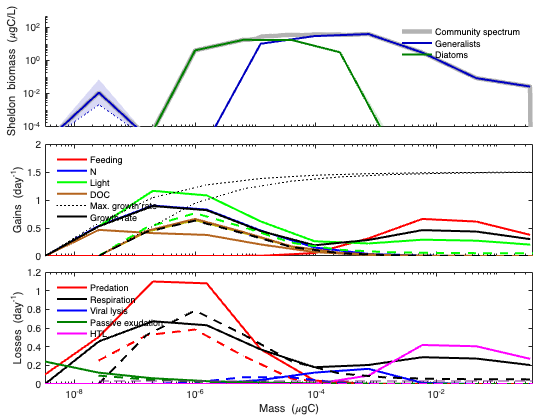

%
% Run simulation:
%
p = parametersChemostat( eval( strcat('setup',sSetup) ) );
p.tEnd = 1000;

p.d = 10^Mixing;
setHTL(10^mHTL, 0.05, true, false);

sim = simulateChemostat(p, L, 10);
%
% Output:
%
plotSizespectrum(sim);



sim = calcFunctions(sim, bPrintSummary=true);

----------------------------------------------
Final total biomass:  5094.830 mgC/m2
Final Chl:               3.290 gChl/m2
Final gross PP:       1644.803 mgC/m2/day
Final net PP:          247.086 mgC/m2/day
Final net bact prod.:  101.129 mgC/m2/day
Final HTL production:  207.727 mgC/m2/day
----------------------------------------------
